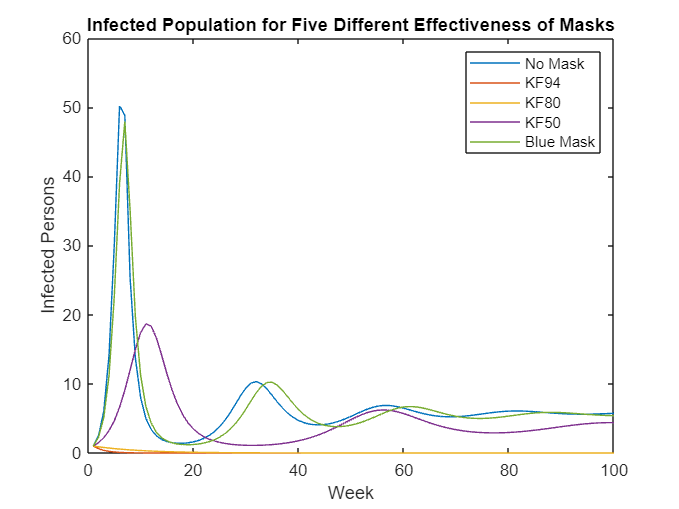

% Define initial state
% A population of 100 persons, 99 susceptible and 1 infectious
s_1 = 99;
i_1 = 1;
r_1 = 0;

%Base infection rate w/o masks etc based on scientific models, 0.178
betaI = 0.05;

%Base recovery rate based on data from other scientific SIR models of
%COVID, 0.015
gamma = 0.5;

%Resuseptibility rate: People lose immunity after 6 months 1/24 weeks,
%0.042
%https://www.ncbi.nlm.nih.gov/pmc/articles/PMC7321055/
alpha = 1/24;

e=[0, 0.94, 0.8, 0.5, 0.1];
c=0.6;

for i=1:5
    beta(i)=betaI*(1-e(i))*(1-c);
    [S(i,:), I(i,:), R(i,:), W] = project1_simulate_sir(s_1, i_1, r_1, beta(i), gamma, alpha, 100);
end

% Plot the data
name=["No Mask", "KF94", "KF80", "KF50", "Blue Mask"];
figure()
for j=1:5
    plot(W, I(j,:), 'DisplayName', name(j)); hold on
end
xlabel("Week")
ylabel("Infected Persons")
title("Infected Population for Five Different Effectiveness of Masks")
legend()

Parameter Sweep

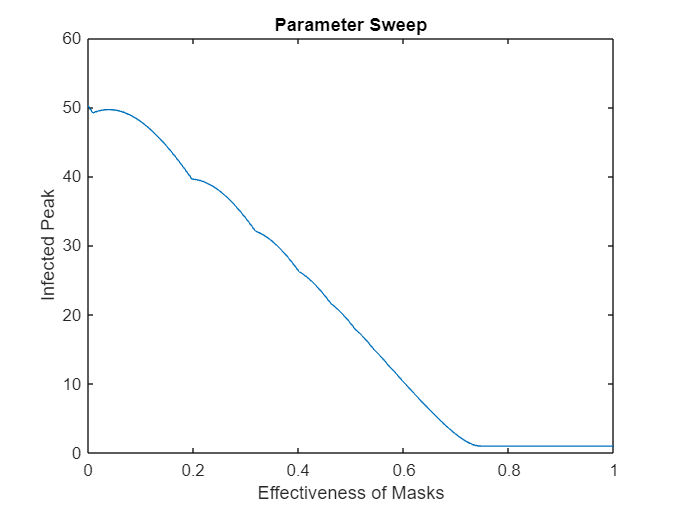

e_all = linspace(0, 1, 1000);
beta_all_e = betaI*(1-e_all)*(1-c);

for j = 1:length(e_all)
    [s, i, r, w] = project1_simulate_sir(s_1, i_1, r_1, beta_all_e(j), gamma, alpha, 100);
    Ipeak_all_e(j)=max(i);
end

figure()
plot(e_all, Ipeak_all_e)
xlabel("Effectiveness of Masks")
ylabel("Infected Peak")
title("Parameter Sweep")


peak_number_of_infected_persons_without_mask = max(I(1,:))

peak_number_of_infected_persons_without_mask = 50.1849

fiftypercent_peak = max(I(1,:))/2

fiftypercent_peak = 25.0924

temp_e = abs(max(I(1,:))/2 - Ipeak_all_e);
idx_e = find(temp_e == min(abs(max(I(1,:))/2 - Ipeak_all_e)))

idx_e = 422

approximate_fiftypercent_peak = Ipeak_all_e(idx_e)

approximate_fiftypercent_peak = 25.0934

approximate_e_for_fiftypercent_peak = e_all(idx_e)

approximate_e_for_fiftypercent_peak = 0.4214

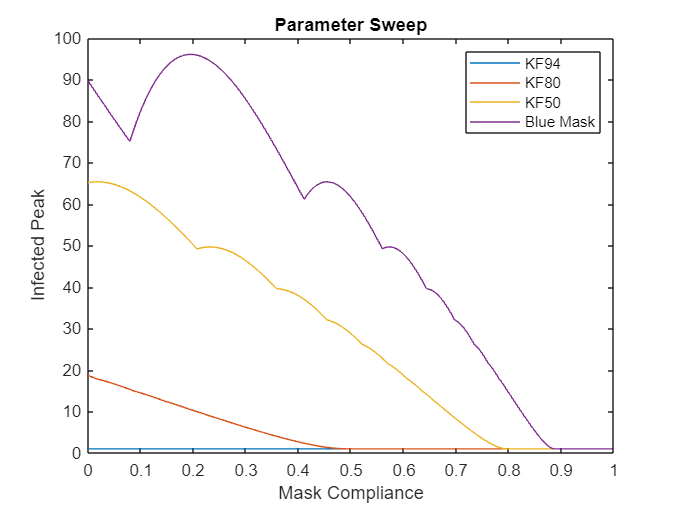



c_all = linspace(0, 1, 1000);
for j = 1:5
    for k = 1:1000
        beta_all_c(j, k) = betaI*(1-e(j))*(1-c_all(k));
    end
end
%beta_all_c = betaI*(1-e_middle)*(1-c_all);

for j = 1:5
    for k = 1:length(e_all)
        [s, i, r, w] = project1_simulate_sir(s_1, i_1, r_1, beta_all_c(j, k), gamma, alpha, 100);
        Ipeak_all_c(j, k)=max(i);
    end
end

figure()
for j = 2:5
    plot(c_all, Ipeak_all_c(j, :), 'DisplayName', name(j)); hold on
end
xlabel("Mask Compliance")
xticks(0: (1/10):1);
ylabel("Infected Peak")
title("Parameter Sweep")
legend('Location', 'northeast')



all(abs(S + I + R - 100) < 1e-3)

ans = 1×100 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


all(abs(s + i + r - 100) < 1e-3)

ans = logical
   1


all(abs(Ipeak_all_e(idx_e) - max(I(1,:))/2) < 1e-3)

ans = logical
   1



beta_42=betaI*(1-0.4214)*(1-0.6)

beta_42 = 0.0116

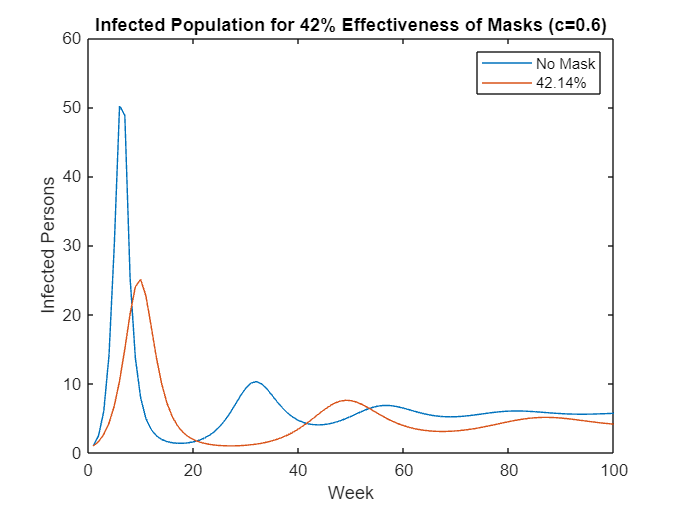

[s_42, i_42, r_42, w_42] = project1_simulate_sir(s_1, i_1, r_1, beta_42, gamma, alpha, 100);

figure()
plot(W, I(1,:), 'DisplayName', 'No Mask'); hold on
plot(W, i_42, 'DisplayName', '42.14%');
xlabel("Week")
ylabel("Infected Persons")
title("Infected Population for 42% Effectiveness of Masks (c=0.6)")
legend()